# EE333 Homework 7.6 MATLAB

Consider the common collector amplifier circuit shown below with β = 100.  Assume all capacitors can be treated as short circuits at the frequency of the source vs.

%circuit values
%these will be used in all calculations that
%I have choosen to show in matlab.
Vp = 9;
Vm= -9;
Vbeo = 0.7;
beta = 100;
Re = 500;
r1 = 10e3;
r2 = 10e3;
rl = 300;
rs = 1e3;
Vt = 0.026;

%since I know i'll need them later, some additional
%calculations are below.

Vth = Vp *(r2/(r1+r2));
Rth = (r1*r2/(r1+r2));
Ib = (Vth - Vbeo)/(Rth + (beta +1)*Re);

rac =  Re;
rdc = (((1/Re)+(1/rl))^-1)+Re;


- Draw the DC equivalent circuit and calculate the DC bias point (ICQ and VCEQ).

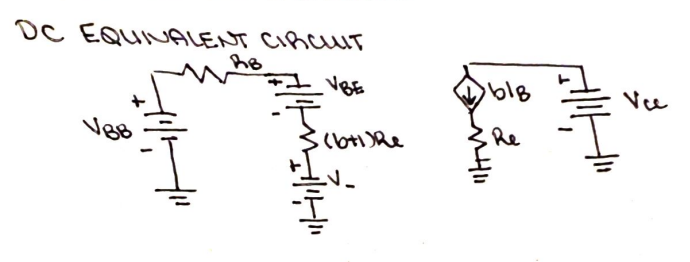

Icq = (Vp/(rac+rdc));
%value is: 0.0076 = 7.6e-3 A

Vceq = (rac/(rac+rdc))*Vp;
%value is:3.7895 V

- Draw the AC equivalent circuit and calculate the small signal voltage gain (*v**o*/*v**s*).

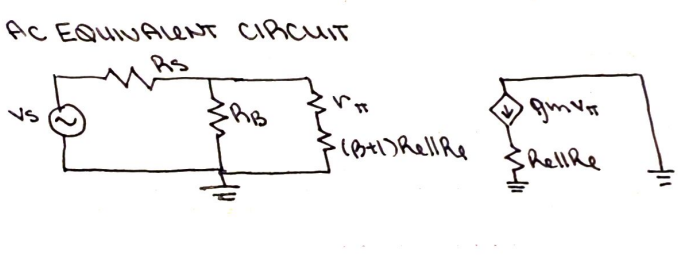

rpi = Vt/Ib;
Ic = beta*Ib;
gm = Ic/Vt;
Av = (rpi*(gm*Re)/(rpi + (beta +1)*Re));
%value:0.9827 V



- Create a MATLAB program to plot the DC and AC load lines on the same graph (i.e. to scale).

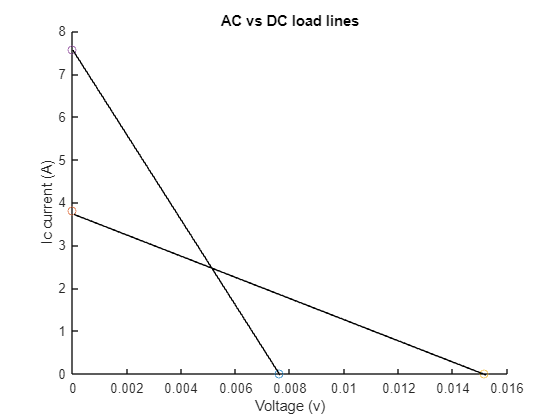

%DC load line
xint = 0.0076;
yint = 3.7995;

%AC load line
yinta = Vceq +Icq*rac;
%value is: 7.5789


xinta = Icq + (Vceq/rac);
%value is: 0.0152;



hold on
plot (xint, 0, "o",0, yint, "o" );
annotation("line", [0.1321 0.8679], [0.4895 0.1071])

plot (xinta, 0, "o",0, yinta, "o" );
annotation("line", [0.1304 0.5], [0.88 0.1071])
hold off;

title ("AC vs DC load lines")
xlabel("Voltage (v)")
ylabel("Ic current (A)")